# Fault Classification

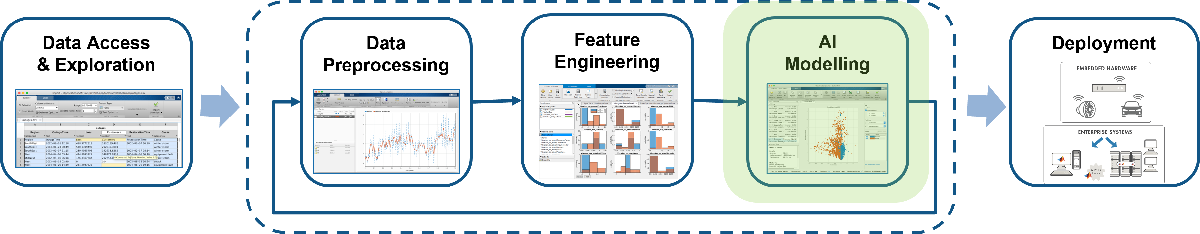

In the previous section (Data Preprocessing), we showed how the data was cleaned and compressed using the changepoint detection algorithm in MATLAB. This greatly reduced the size of the data and also made the feature engineering workflow more effective. 

We are now in the AI Modelling stage of the PdM workflow. In this script, we will be tackling fault classification i.e., answer the question- which subsystem is most likely to fail first. In this live script, we will demonstrate how to use the extracted features and labels, to train a machine learning model to classify the fault type based on the feature extracted from the flight sensor data. We also show to interactively train and test a large number of machine learning models using the Classification Learner app.

MATLAB provides a wide range of AI modelling, training and testing capabilities through its Statistics and Machine Learning Toolbox, Deep Learning Toolbox, Parallel Computing Toolbox, etc. Engineers can also leverage MATLAB-Python interoperability to bring in their Tensorflow, PyTorch AI models into MATLAB for V&V and deployment purposes.

**Reference and Dataset Source:** *M. Chao, C.Kulkarni, K. Goebel and O. Fink (2021). "Aircraft Engine Run-to-Failure Dataset under real flight conditions", NASA Ames Prognostics Data Repository (*[*http://ti.arc.nasa.gov/project/prognostic-data-repository*](http://ti.arc.nasa.gov/project/prognostic-data-repositoryhttps://ti.arc.nasa.gov/tech/dash/groups/pcoe/prognostic-data-repository/#turbofan-2)*), NASA Ames Research Center, Moffett Field, CA*

## Load Data and Check Labels

% Load our already extracted features 
load("featureTables.mat","normalizedDevData","normalizedTestData");

disp(head(normalizedDevData));

    mean_Mach    sem_Mach    std_Mach    skewness_Mach    var_Mach    min_Mach    max_Mach    range_Mach     mean_Nc      sem_Nc       std_Nc      skewness_Nc     var_Nc       min_Nc      max_Nc     range_Nc      mean_Nf      sem_Nf      std_Nf     skewness_Nf     var_Nf      min_Nf      max_Nf     range_Nf    mean_P15     sem_P15       std_P15     skewness_P15    var_P15     min_P15     max_P15     range_P15    mean_P2      se

Dev Set

% disp(groupsummary(normalizedDevData,"FailureMode"))
tabulate(normalizedDevData.FailureMode)

      Value    Count   Percent
    Healthy     1340     29.55%
        HPT      593     13.08%
        LPT      314      6.92%
  HPT + LPT      579     12.77%
        Fan      407      8.97%
        HPC      338      7.45%
  HPC + LPC      334      7.36%
        All      630     13.89%


Test Set

% disp(groupsummary(normalizedTestData,"FailureMode"))
tabulate(normalizedTestData.FailureMode)

      Value    Count   Percent
    Healthy      947     32.23%
        HPT      230      7.83%
        LPT      231      7.86%
  HPT + LPT      416     14.16%
        Fan      265      9.02%
        HPC      215      7.32%
  HPC + LPC      222      7.56%
        All      412     14.02%


## Train Fault Classification Model

We already have a split testing and training set as the data was initially set up with some portion reserved. 

The next thing to evaluate is which of the many features we extracted is the most valuable in terms of differentiating between the different failure modes we might be in. We have an app which allows you to explore some Feature Engineering in addition to different built-in learning algorithms. 

For those not familiar with this process, we have an [Introduction to Feature Selection](https://www.mathworks.com/help/stats/feature-selection.html) page to help get you started. 

% Now we can open the classification learner application. 
trainData =normalizedDevData;
trainData.RUL=[];
trainData.uniqueID=[];
TrainedClassifier = trainClassifier2(trainData);

### Dimensionality Reduction with ANOVA test

ANOVA (analysis of variance) tests whether the means of a numerical variable differ significantly across two or more groups. Here, for each

predictor (numerical feature) we perform a one-way ANOVA across the FailureMode categories. A small p-value indicates that the predictor's

mean values are unlikely to be the same across all failure-mode groups, implying that the feature helps discriminate between classes.

We use ANOVA as a simple univariate filter to rank features by how strongly they vary with the class label before proceeding to model

training or more sophisticated multivariate selection.

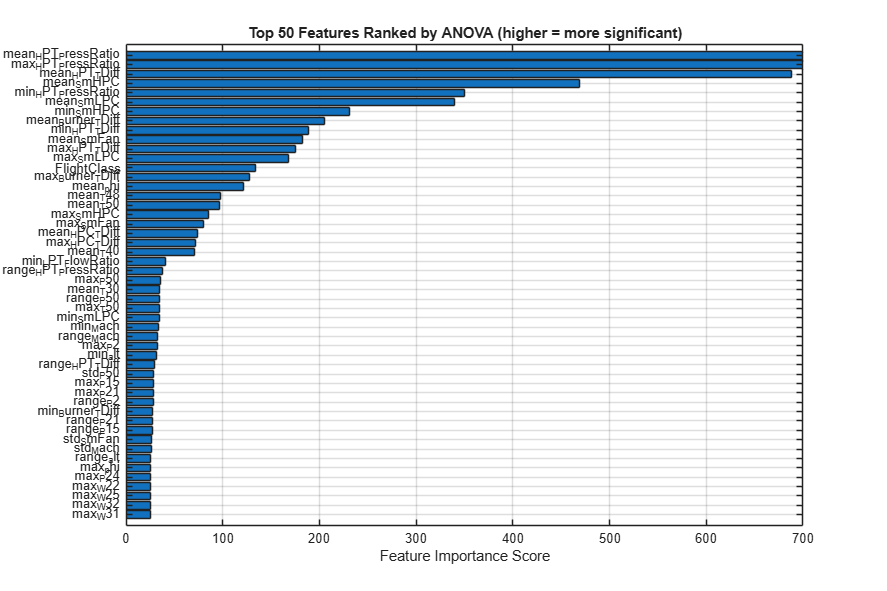

% Extract predictors and response
inputTable = trainData;
predictorNames = inputTable.Properties.VariableNames(1:end-1);
predictors = inputTable(:, predictorNames);
response = inputTable.FailureMode;
classNames = categorical({'Healthy'; 'HPT'; 'LPT'; 'HPT + LPT'; 'Fan'; 'HPC'; 'HPC + LPC'; 'All'}, {'Healthy' 'HPT' 'LPT' 'HPT + LPT' 'Fan' 'HPC' 'HPC + LPC' 'All'});

% Feature Ranking and Selection
% Data is already normalized and there are no categorical predictors.
% Replace Inf/-Inf values with NaN to handle any non-finite entries
predictors = standardizeMissing(predictors, {Inf, -Inf});

% Convert table to numeric matrix directly since predictors are normalized and none are categorical
predictorMatrix = table2array(varfun(@double, predictors));

% Prepare response vector
responseVector = grp2idx(response);

% Rank features using ANOVA (one-way) and collect p-values
numPredictors = size(predictorMatrix, 2);
pValues = zeros(1, numPredictors);
for i = 1:numPredictors
    pValues(i) = anova1(predictorMatrix(:,i), responseVector, 'off');
end

% Some p-values may be extremely small and underflow to 0, producing Inf
% when taking -log. Identify zeros and set them to smallest nonzero p-value
% for ranking, but remember which are truly zero so we can mark them as Inf on the plot.
isZeroP = (pValues == 0);
nonzeroP = pValues(~isZeroP);
if isempty(nonzeroP)
    minNonzero = realmin; % fallback
else
    minNonzero = min(nonzeroP);
end

% For ranking purposes, avoid NaN or zeros causing issues
safeP = pValues;
safeP(isnan(safeP)) = 1;        % least significant
safeP(isZeroP) = minNonzero;   % give them the smallest nonzero value for ranking

[~,featureIndex] = sort(-log(safeP), 'descend');

% Plot top-N features by significance (log p-value)
topN = 50; % set default number of top features to display
topN = min(topN, numPredictors);
topIdx = featureIndex(1:topN);

% Compute scores for plotting: use -log(p), but set those original zero p-values to Inf
rawScores = -log(pValues);
plotScores = rawScores(topIdx);

% Determine finite max to place Inf bars slightly above
finiteScores = plotScores(isfinite(plotScores));
if isempty(finiteScores)
    maxFinite = 0;
else
    maxFinite = max(finiteScores);
end
infBarHeight = maxFinite + max(1,0.1*maxFinite); % offset for Inf bars

% Replace -Inf/Inf from -log of zero p-values with Inf marker value
isInfScore = ~isfinite(plotScores);
plotScores(isInfScore) = infBarHeight;

topNames = predictorNames(topIdx);

figure('Name','Top Features by -log(p)','Position',[100 100 900 600]);
barh(flip(plotScores));
yticks(1:topN);
yticklabels(flip(topNames));
xlabel('Feature Importance Score');
title(sprintf('Top %d Features Ranked by ANOVA (higher = more significant)', topN));
grid on;

% Annotate Inf bars: add red ticks/text for those that were infinite
hold on;
% find indices (in plotted order) of Inf scores
plottedIsInf = flip(isInfScore); % because barh is flipped
yInf = find(plottedIsInf);
for k = 1:numel(yInf)
    yi = yInf(k);
    % x position at end of bar
    x = plotScores(end-yi+1); % since flipped, compute corresponding value
    % place a red triangle marker at (x, yi)
    plot(x, yi, 'r^', 'MarkerFaceColor','r', 'MarkerSize',6);
    % add text label 'Inf' slightly to the right
    % text(x + 0.02*max(1, maxFinite), yi, 'Inf', 'Color','r', 'FontWeight','bold', 'VerticalAlignment','middle');
end
hold off;
xlim([0 700])

### **Remove Class Bias**

tabulate(normalizedDevData.FailureMode)

      Value    Count   Percent
    Healthy     1340     29.55%
        HPT      593     13.08%
        LPT      314      6.92%
  HPT + LPT      579     12.77%
        Fan      407      8.97%
        HPC      338      7.45%
  HPC + LPC      334      7.36%
        All      630     13.89%



trainData =normalizedDevData;
trainData.RUL=[];
trainData.uniqueID=[];

[trainData,Weights] = UpSampleDownweight(trainData,"FailureMode");
tabulate(trainData.FailureMode)

      Value    Count   Percent
    Healthy     1340     12.50%
        HPT     1340     12.50%
        LPT     1340     12.50%
  HPT + LPT     1340     12.50%
        Fan     1340     12.50%
        HPC     1340     12.50%
  HPC + LPC     1340     12.50%
        All     1340     12.50%


Copying objective function to workers...
Done copying objective function to workers.
Learner types to explore: ensemble, knn, nb, net, svm, tree
Total iterations (MaxObjectiveEvaluations): 595
Total time (MaxTime): 1500

|====================================================================================================================================================|
| Iter | Active  | Eval   | Validation | Time for training | Observed min    | Training set | Learner      | Hyperparameter:                 Value   |
|      | workers | result | loss       | & validation (sec)| validation loss | size         |              |                                         |
|====================================================================================================================================================|
|    1 |       8 | Best   |    0.68148 |            1.1287 |         0.68148 |          134 |          knn | NumNeighbors:                         3 |
|    2 |       8 | Accep

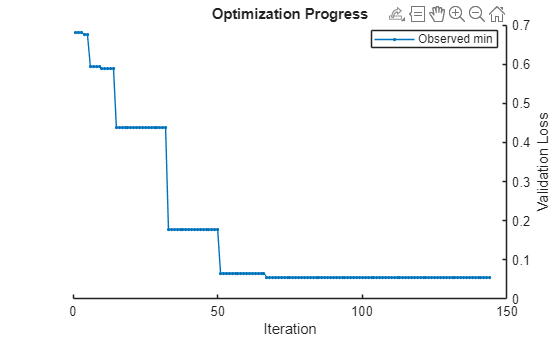


__________________________________________________________
Optimization completed.
Total iterations: 144
Total elapsed time: 1490.7358 seconds
Total time for training and validation: 9143.8292 seconds

Best observed learner is a net model with:
	Learner:                   net
	Activations:           sigmoid
	Standardize:              true
	Lambda:             1.1332e-05
	LayerSizes:                 57
Observed validation loss: 0.055482
Time for training and validation: 155.9449 seconds

Documentation for fitcauto display


% trainData = trainData(:,[topNames {'FailureMode'}]);
ashaOptions = struct("optimizer","asha","UseParallel",true,"MaxTime",1500);
[ashaMdl, ashaResults] = fitcauto(trainData, "FailureMode","Weights",Weights,"HyperparameterOptimizationOptions",ashaOptions);

## Test the Model

We want to make sure the model performs as well on data it has not encountered in training. So, we can use the testing set that comes with this dataset in order to check that. 

[YPred, scores] = predict(ashaMdl, normalizedDevData);
% [YPred, scores] = TrainedClassifier.predictFcn(normalizedDevData);
accuracyTrain = sum(YPred==normalizedDevData.FailureMode)/height(YPred)

accuracyTrain = 0.9985

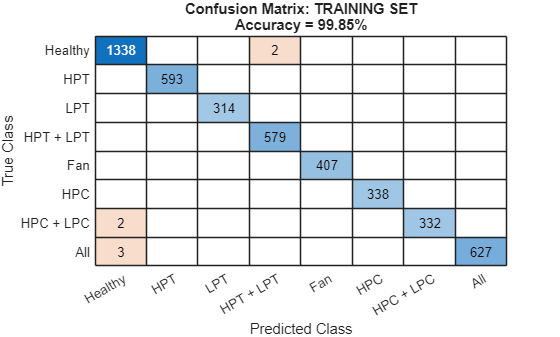

figure; confusionchart(normalizedDevData.FailureMode,YPred)
title(sprintf('Confusion Matrix: TRAINING SET\nAccuracy = %.2f%%', accuracyTrain*100));


[YPredTest, scoresTest] = predict(ashaMdl, normalizedTestData);
% [YPredTest, scoresTest] = TrainedClassifier.predictFcn(normalizedTestData);
accuracyTest = sum(YPredTest==normalizedTestData.FailureMode)/height(YPredTest)

accuracyTest = 0.9452

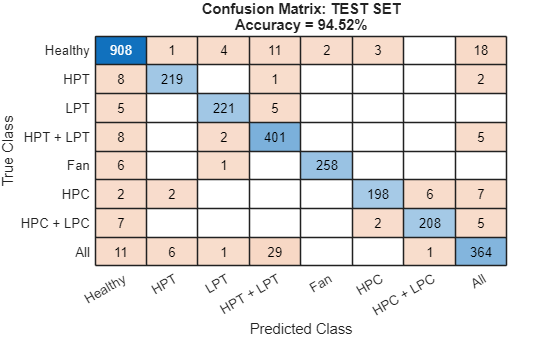

figure; confusionchart(normalizedTestData.FailureMode,YPredTest)
title(sprintf('Confusion Matrix: TEST SET\nAccuracy = %.2f%%', accuracyTest*100));

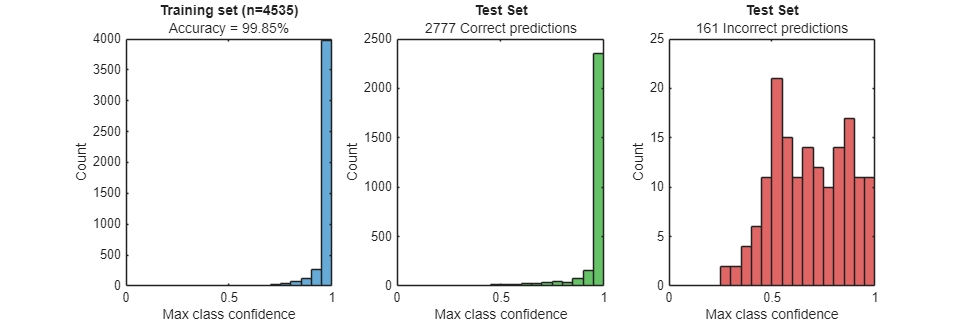


% Histogram of highest training-set confidence (max over classes) irrespective of prediction
trainMaxScores = max(scores, [], 2);
figure('Position',[0 0 1200 400]);
subplot(1,3,1);
histogram(trainMaxScores, 'BinEdges', linspace(0,1,21), 'FaceColor',[0 0.4470 0.7410]);
xlabel('Max class confidence'); ylabel('Count');
title(sprintf('Training set (n=%d)', numel(trainMaxScores)));
subtitle(sprintf('Accuracy = %.2f%%', accuracyTrain*100));
xlim([0 1]); 

% Determine which predictions are correct
isCorrect = YPredTest == normalizedTestData.FailureMode;

% Assume scoresTest columns correspond to class order given by the model.
classNames = cellstr(unique(normalizedTestData.FailureMode));
nClasses = numel(classNames);

% For each observation, extract the confidence score of the predicted class
predClassIdx = zeros(height(normalizedTestData),1);
for i = 1:height(normalizedTestData)
    % find index of predicted class in classNames
    predClassIdx(i) = find(strcmp(classNames, char(YPredTest(i))),1);
end
predScores = zeros(size(predClassIdx));
for i = 1:numel(predClassIdx)
    idx = predClassIdx(i);
    if idx>=1 && idx<=size(scoresTest,2)
        predScores(i) = scoresTest(i,idx);
    else
        predScores(i) = NaN;
    end
end

% Split scores into correct and incorrect
scoresCorrect = predScores(isCorrect);
scoresIncorrect = predScores(~isCorrect);

% Plot histograms for test correct vs incorrect in the remaining subplots
subplot(1,3,2);
histogram(scoresCorrect, 'BinEdges', linspace(0,1,21), 'FaceColor',[0 .6 0]);
xlabel('Max class confidence'); ylabel('Count');
title('Test Set');
subtitle(sprintf('%d Correct predictions', numel(scoresCorrect)))
xlim([0 1]); 

subplot(1,3,3);
histogram(scoresIncorrect, 'BinEdges', linspace(0,1,21), 'FaceColor',[0.8 0 0]);
xlabel('Max class confidence'); ylabel('Count');
title('Test Set');
subtitle(sprintf('%d Incorrect predictions', numel(scoresIncorrect)))
xlim([0 1]);

# **Model Explainability**

## **SHAPLEY **

Create a shapley object that explains the predictions for multiple query points. For faster computation, shapley subsamples 100 observations from the predictor data in blackbox to compute the Shapley values. Specify the sampled observations as the query points in the call to the fit object function.

X = trainData(:, ashaMdl.PredictorNames);
Y = trainData.FailureMode;
rng("default") % For reproducibility
explainer = shapley(ashaMdl, X);
queryPoints = explainer.X(explainer.SampledObservationIndices,:);
explainer = fit(explainer,queryPoints);

For a classification model, fit computes Shapley values using the predicted class scores, and stores them in the Shapley property of the shapley object. Because explainer contains Shapley values for multiple query points, display the mean absolute Shapley values instead.

explainer.MeanAbsoluteShapley

ans = 362×9 table
       Predictor        Healthy        HPT          LPT       HPT + LPT       Fan          HPC       HPC + LPC       All   
    _______________    _________    _________    _________    _________    _________    _________    _________    _________

    "mean_Mach"        0.0091258     0.010375     0.017262    0.0053093    0.0065078     0.046816     0.075345     0.019136
    "sem_Mach"         0.0034876    0.0017665    0.0021443     0.002536    0.0010266    0.0025213    0.0039206    0.0061264
    "std_Mach"         0.0016961    0.0017606     0.002159    0.0023738    0.0011885    0.0023003    0.0029779    0.0034268
    "skewness_Mach"    0.0021063    0.0015949    0.0030

For each predictor and class, the mean absolute Shapley value is the absolute value of the Shapley values, averaged across all query points. For faulty, the "d_ngx_trq_margin" predictor has a noticeably greater mean absolute Shapley value than the other predictors.

Visualize the distribution of the Shapley values for faulty class by using the boxchart object function.

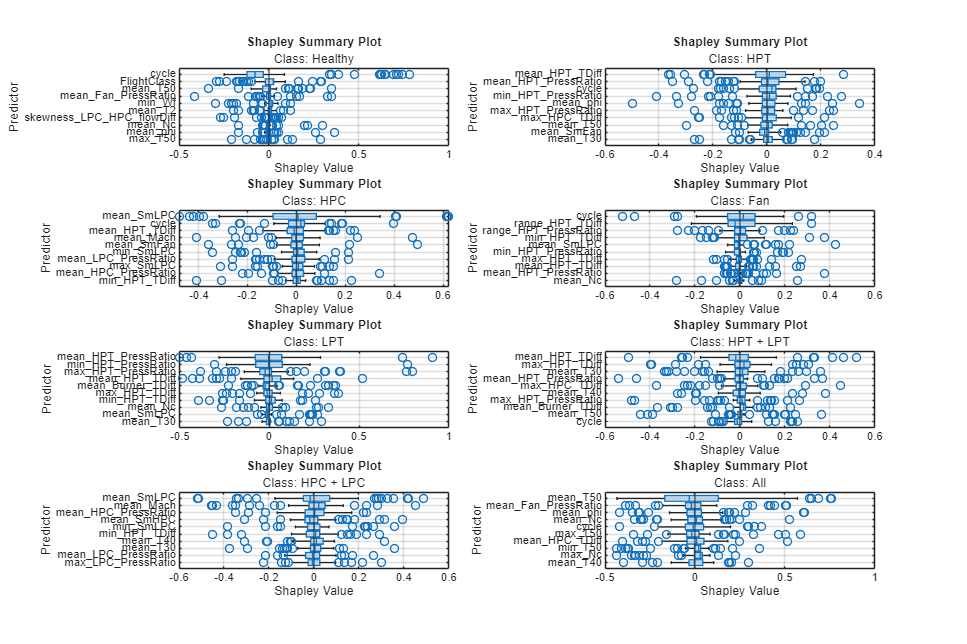

figure('Position',[10 10 1200 800]); 
subplot 421
boxchart(explainer,ClassName={'Healthy'}) % Predictor Importance for Healthy Data
subplot 422
boxchart(explainer,ClassName={'HPT'}) % Predictor Importance for HPT failures
subplot 423
boxchart(explainer,ClassName={'HPC'}) 
subplot 424
boxchart(explainer,ClassName={'Fan'}) 
subplot 425
boxchart(explainer,ClassName={'LPT'}) 
subplot 426
boxchart(explainer,ClassName={'HPT + LPT'}) 
subplot 427
boxchart(explainer,ClassName={'HPC + LPC'})
subplot 428
boxchart(explainer,ClassName={'All'}) 

#### **Interpretation:**

- Features near zero (short boxes, tight clustering) have **minimal impact** on the NN’s prediction.

## Partial Dependence Plot (Global Effect)

PDP isolates **how a single feature affects the model output**, averaging over all other features.  

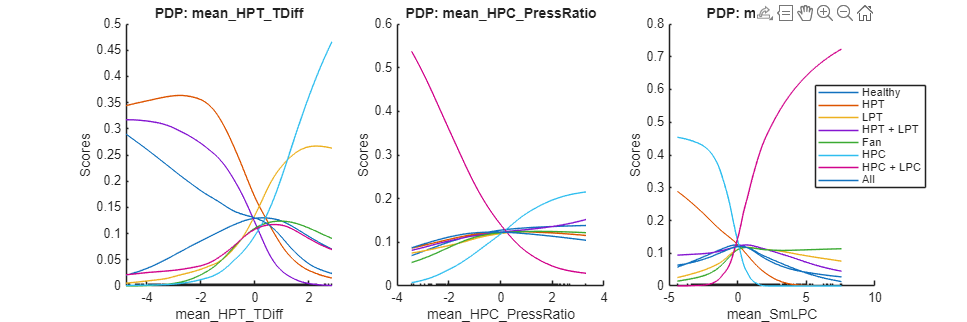

X = trainData(:, ashaMdl.PredictorNames);

figure('Position',[10 10 1200 400]);
subplot 131
feature = "mean_HPT_TDiff";   % example
plotPartialDependence(ashaMdl, feature, ashaMdl.ClassNames, X); legend off;
title("PDP: " + feature,'Interpreter','none');
subplot 132
feature = "mean_HPC_PressRatio";   % example
plotPartialDependence(ashaMdl, feature, ashaMdl.ClassNames, X);legend off;
title("PDP: " + feature,'Interpreter','none');
subplot 133
feature = "mean_SmLPC";   % example
plotPartialDependence(ashaMdl, feature, ashaMdl.ClassNames, X); 
title("PDP: " + feature,'Interpreter','none');

**Interpretation**

## Test Model by Flight Phases

Climb:

Cruise:

Descent:

All:

*© 2022-2026 The MathWorks, Inc.*

### Helper Functions

function [trainData,Weights] = UpSampleDownweight(data,varName)
% Upsample minority classes and downweight majority classes for multiclass data.
% Adds up to 1% random noise to numerical features for duplicated minority samples.
%
% Inputs:
%   data    - table containing predictors and response
%   varName - name of response variable (string or char)
%
% Outputs:
%   trainData - table with balanced classes (original + generated samples)
%   Weights   - vector of observation weights (same length as trainData)

totalObs = height(data);

% Get class counts
tbl = tabulate(data.(varName));
% Ensure tbl is cell array for consistent indexing
if ~iscell(tbl)
    tbl = num2cell(tbl);
end

% Extract class names and counts robustly
classNames = tbl(:,1);
classCounts = cell2mat(tbl(:,2));
% Remove NaN or empty class names (safety)
valid = ~cellfun(@(c) any(cellfun(@(x) isequal(x,c), {''})), classNames) & ~isnan(classCounts);
classNames = classNames(valid);
classCounts = classCounts(valid);

% Identify target size (max count)
targetCount = max(classCounts);

% Precompute numeric variable names to add noise to
varTypes = varfun(@class, data, 'OutputFormat', 'cell');
isNumericVar = ismember(varTypes, {'double','single','int8','int16','int32','int64','uint8','uint16','uint32','uint64'});
numericVars = data.Properties.VariableNames(isNumericVar);
% Exclude response variable if numeric
numericVars(strcmp(numericVars,varName)) = [];

rng('shuffle');

generatedRows = table(); % empty table for concatenation

for k = 1:numel(classNames)
    cname = classNames{k};
    count = classCounts(k);
    if count < targetCount
        nNeeded = targetCount - count;
        % Extract minority class data
        isClass = ismember(data.(varName), cname);
        classData = data(isClass,:);
        nClassObs = height(classData);
        % Determine number of full replications and remainder sampling
        nCopies = floor(nNeeded / nClassObs);
        nRemainder = mod(nNeeded, nClassObs);
        % Build candidate pool by repeating table
        pool = classData;
        if nCopies > 0
            pool = repmat(classData, nCopies+1, 1); % +1 for initial set
        end
        % Sample exactly nNeeded rows without replacement if possible, else with replacement
        if height(pool) >= nNeeded
            samples = datasample(pool, nNeeded, 'Replace', false);
        else
            samples = datasample(pool, nNeeded, 'Replace', true);
        end
        % Add up to 1% random noise to numeric features for these generated samples
        if ~isempty(numericVars)
            for v = 1:numel(numericVars)
                var = numericVars{v};
                col = samples.(var);
                % Compute scale per variable based on std of original classData
                origCol = classData.(var);
                scale = std(origCol);
                if isnan(scale) || scale==0
                    % fallback to range-based small scale
                    rngRange = range(origCol);
                    scale = rngRange;
                end
                if isempty(scale) || scale==0
                    scale = 1; % ultimate fallback
                end
                noiseAmplitude = 0.01 * abs(scale); % 1% of std/range
                noise = noiseAmplitude .* randn(size(col));
                % Preserve integer types by rounding if original var is integer
                if isinteger(origCol)
                    col = col + cast(round(noise), class(col));
                    samples.(var) = col;
                else
                    samples.(var) = col + noise;
                end
            end
        end
        generatedRows = [generatedRows; samples]; %#ok<AGROW>
    end
end

% Combine original data and generated rows
if isempty(generatedRows)
    trainData = data;
else
    trainData = [data; generatedRows];
end

% Construct Weights: start with ones divided by total original observations
numTrain = height(trainData);
Weights = ones(numTrain,1) ./ totalObs;

% Downweight classes proportional to original counts to avoid majority influence
% For each class, scale weights so that total weight per class equals original class proportion (or equalize?)
% Requirement: output should have equal distribution in response variable, and corresponding Weights.
% We'll set per-observation weights so that total weight per class equals original class count / totalObs.
% That keeps overall class importance proportional to original prevalence while balancing sample counts.

% Desired total weight per class = original_count / totalObs
desiredClassTotalWeight = containers.Map;
for k = 1:numel(classNames)
    desiredClassTotalWeight(classNames{k}) = classCounts(k) / totalObs;
end

% Compute current counts in trainData per class and set per-observation weight
for k = 1:numel(classNames)
    cname = classNames{k};
    isClassTrain = ismember(trainData.(varName), cname);
    nTrainClass = sum(isClassTrain);
    if nTrainClass > 0
        perObsWeight = desiredClassTotalWeight(cname) / nTrainClass;
        Weights(isClassTrain) = perObsWeight;
    end
end

% Shuffle the training data and Weights
shuffle = randperm(numTrain);
trainData = trainData(shuffle,:);
Weights = Weights(shuffle);

end